filelist =[
"data_08-Apr-2025_15-55-45.mat" 
]

filelist = "data_08-Apr-2025_15-55-45.mat"

exp_id = 1;

filename = "lab5/data/"+filelist(exp_id);
data = load(filename).data(:,1:end-2000);
t = data(1,:);
time = t;
S_inp = data(12,:); %D0
S_out = data(2,:);  %Theta 0
om = 15 + 3*floor((t/30));
% figure
% plot(t,om)
% figure
% plot(t,S_inp)
% figure
% plot(t,S_out)
do_plots = true

do_plots = logical
   1


slices = sliceTimeSeries(t,om);

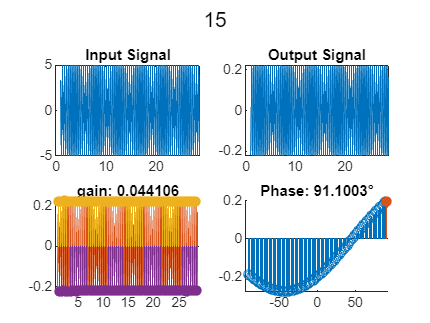

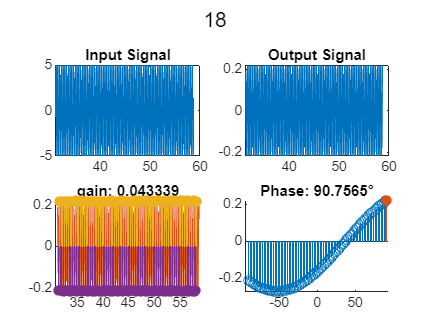

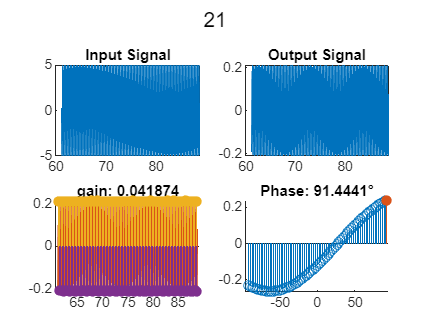

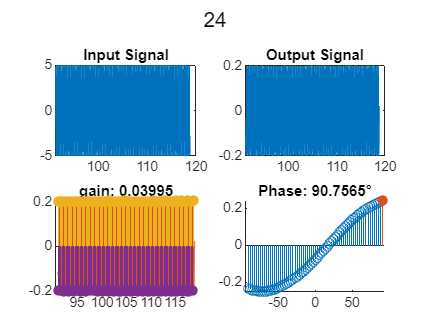

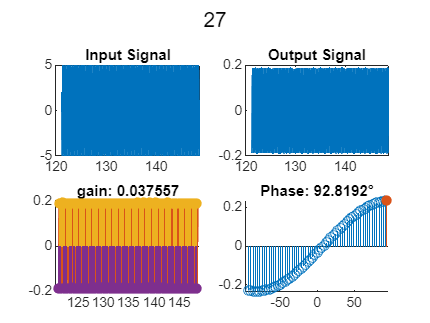

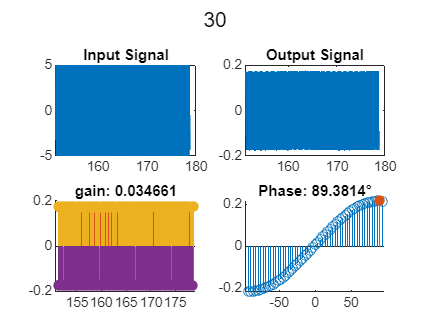

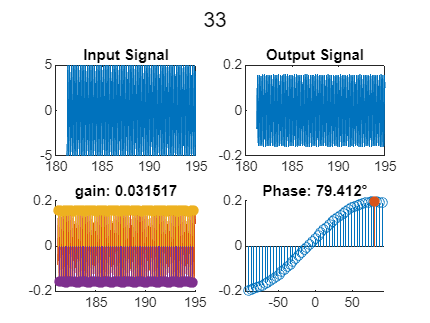

tstart_d =1;
tend_d = 1;

for i = 1:size(slices,2)
    omega = slices{i}.f;
    focus = slices{i};

    t_start_idx = time2index(focus.t_start+tstart_d);
    t_end_idx = time2index(focus.t_end-tend_d);
   

    t_focus= time(t_start_idx:t_end_idx);
    om_focus= om(t_start_idx:t_end_idx);
    i_focus= S_inp(t_start_idx:t_end_idx);
    o_focus= S_out(t_start_idx:t_end_idx);
    if do_plots
        figure
        subplot(2,2,1)
            plot(t_focus,i_focus)
            title("Input Signal")
        subplot(2,2,2)
            plot(t_focus,o_focus)
            title("Output Signal")
        subplot(2,2,[3 4])
    end
    [phase, gain, phase_del] = NewSweepAnalysis(t_focus,i_focus, o_focus, omega, do_plots);
    slices{i}.phase = phase;
    slices{i}.gain = gain;
    slices{i}.phase_del = phase_del;
end


 [freqs,phases, gains, phase_dels] = flatten(slices);


tableofData = [freqs; phases; gains]' ;



    %get model params
mu = -1.4684;
tau =  0.0409;
kp = -21.4;
kd = -0.43;

G = tf([mu],[tau 1 0]);
C = pid(kp,0,kd);
L=G*C;
T = feedback(G,C,-1);
% T_d = c2d(T,1/500);
[g_T,p_T,ome_T] = bode(T,{1,40});
ang_T = 1*(reshape(p_T(1,1,:),1,[]));
g_T_f = reshape(g_T(1,1,:),1,[]);

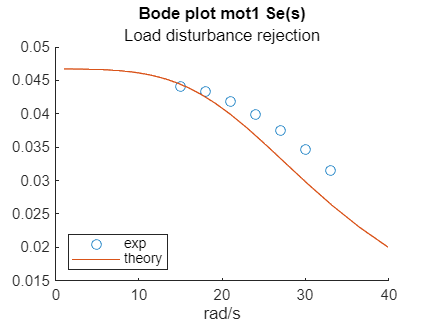


omegas = tableofData(:,1);
phases = tableofData(:,2);
gains = tableofData(:,3);

% subplot(2,1,1)
figure

scatter(omegas,gains)
title("Bode plot mot1 Se(s)")
hold on
plot(ome_T,g_T_f)
% plot(tid_w,g_Tid_f)
% yscale("log")
subtitle("Load disturbance rejection")
xlabel("rad/s")
% ylim([0 1.1])
% ylim([0 1.1])
legend(["exp", "theory"], "Location", 'southwest')
hold  off

% 
% subplot(2,1,2)
% plot(omegas,rad2deg(phases))
% hold on
% plot(ome_T,ang_T)
% title("Phase")
% xlabel("rad/s")
% ylabel("deg")
% hold  off
% legend(["exp","theory"])


function idx = time2index(time)
idx = floor(time/0.002)+1;
end

function [freqs, phases, gain, phase_dels] = flatten(slices)
    freqs = [];
    phases = [];
    gain = [];
    phase_dels = [];
    for i = 1:size(slices,2)
    freqs(i) = slices{i}.f;
    phases(i) = slices{i}.phase;
    gain(i) = slices{i}.gain;
    phase_dels(i) = slices{i}.phase_del;
    end

end